# Longitudinal Vehicle - Test Case

## Brake3 - Vary Brake Force

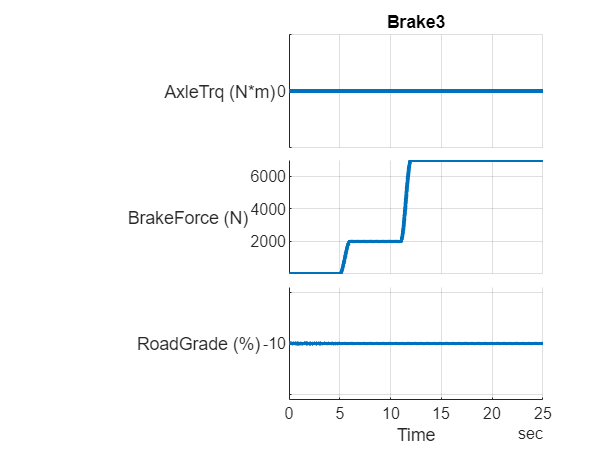

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

Vehicle1D_harness_setup

vehSigBuilder = Vehicle1D_InputSignalBuilder;
vehSigBuilder.Plot_tf = true;

inpData = Brake3(vehSigBuilder, ...
            InitialVehicleSpeed_kph = 60, ...
            RoadGrade_Const_pct = -10, ...
            AxleTorque_Const_Nm = 0, ...
            BrakeForce_1_N = 0, ...
            BrakeForce_2_N = 2000, ...
            BrakeForce_3_N = 7000, ...
            BrakeChange_1_StartTime = seconds(5), ...
            BrakeChange_1_EndTime = seconds(5 + 1), ...
            BrakeChange_2_StartTime = seconds(6 + 5), ...
            BrakeChange_2_EndTime = seconds(11 + 1), ...
            StopTime = seconds(12 + 13) );

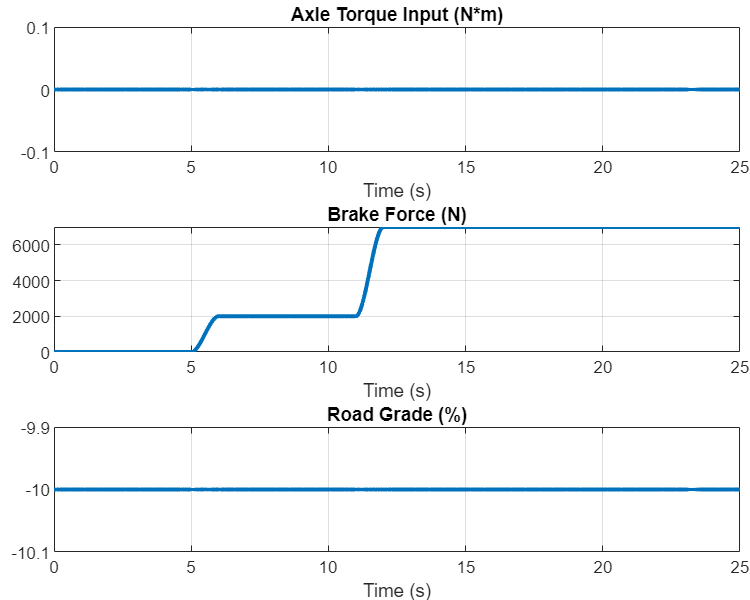

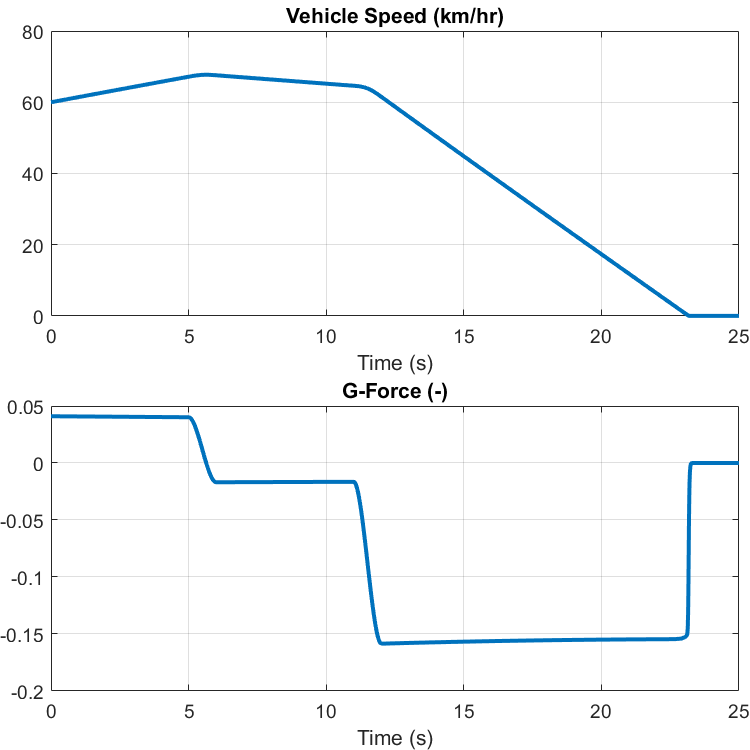

simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn, "vehicle_InputSignals", inpData.Signals);
simIn = setVariable(simIn, "vehicle_InputBus", inpData.Bus);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));

v0 = inpData.Options.InitialVehicleSpeed_kph;

simIn = setBlockParameter(simIn, ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x", num2str(v0), ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x_unit", "km/hr", ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x_priority", "high");

simOut = sim(simIn);

Vehicle1D_plotResults(simOut.logsout);

*Copyright 2020-2022 The Mathworks, Inc.*